clear all

run("biomass_at1000.m")


%max=26.0e-6;
figure 
Xgrid=400

Xgrid = 400

Ygrid=400

Ygrid = 400


alpha=0.2;
beta=0.5;
var_0=full(biomass_1000_0);
var_1=full(biomass_1000_1);
max1=max(var_1(:,:))

max1 = 1.0e-06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


max2=max(var_0(:,:))

max2 = 1.0e-06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


max=max([max1 max2])

max = 9.3544e-07

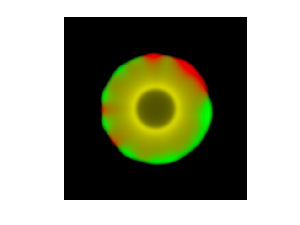


for x=1:Xgrid
    for y=1:Ygrid
        C(x,y,1)=var_0(x,y)/(max);
        C(x,y,2)=var_1(x,y)/(max);
        C(x,y,3)=0.0;
        %if C(x,y,1)~=0 && C(x,y,2)~=0
        %C(x,y,1)=C(x,y,1)/(C(x,y,1)+0.5);
        %C(x,y,2)=C(x,y,2)/(C(x,y,2)+0.5);
        %C(x,y,1)=alpha*C(x,y,1)+beta;
        %C(x,y,2)=alpha*C(x,y,2)+beta;
        %end
    end
end

s=image(C);

%s=pcolor(1:Xgrid,1:Ygrid,var)
%hold on
%s.EdgeColor = 'none';
ax=gca;
%zlim([0 3]);
ax.Box = 'off';
ax.XGrid = 'off';
ax.YGrid = 'off';
ax.ZGrid = 'off';
ax.XTick = [];
ax.YTick = [];
ax.ZTick = [];
ax.ZColor = 'none';
ax.YColor = 'none';
ax.XColor = 'none';
%colormap(ax,pink);
axis equal

%view(azymuth,elevation)hh
%clear var


imwrite(C,"biomass_RG_t1000.png")